clear; clc;

## Create time-series data:

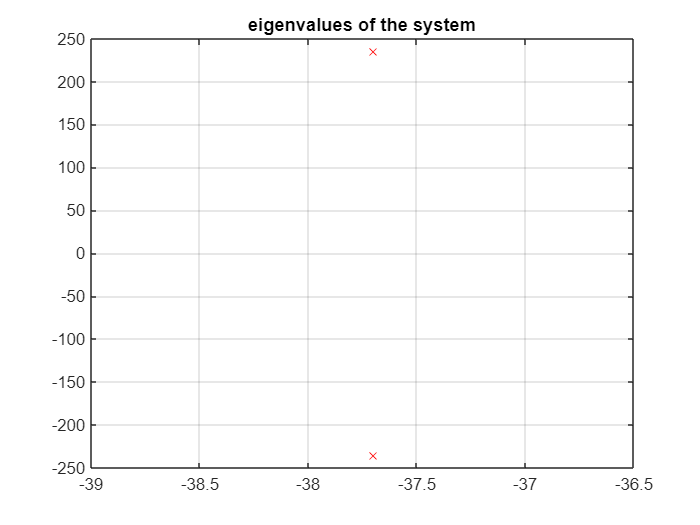

s= tf('s'); h = 0.001; t = 0:h:0.1;
vs = ones(length(t),1);                    % step excitation
R = 0.1; L = 0.5/377; C = 1/0.2/377;
sys = 1/(R*C*s+L*C*s^2+ 1);                % from vs to capacitor voltage 
eig_sys = pole(sys);
figure;
plot(eig_sys, 'rX');
grid on; title('eigenvalues of the system');

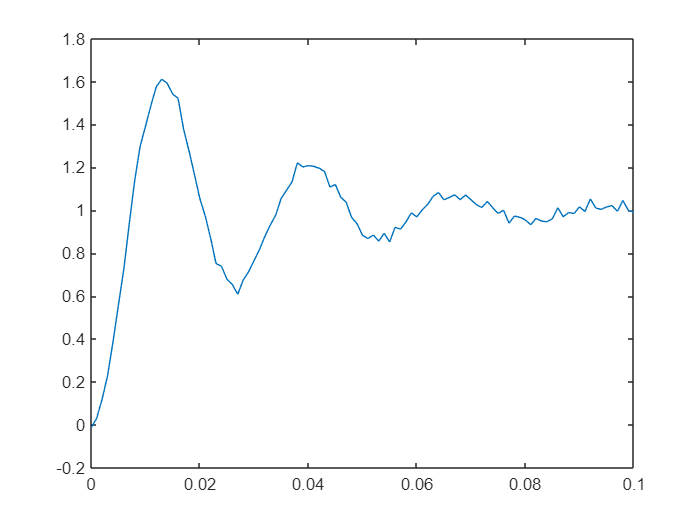

vc = lsim(sys, vs, t); [n_vc, m_vc] = size(vc);
vc1 = vc + (rand(n_vc, m_vc) -0.5)*0.1/max(vc); % add noise
figure;
plot(t, vc1);

ya = vc1; 

## Matrix Pencil

examine the size of the data

n_ch_MP = size(ya, 2) 

n_ch_MP = 1

N_MP = size(ya,1)-1

N_MP = 100

dT = h; t1 = 0:dT:N_MP*dT;

Contruct data Hankel matrix

choose_L=floor(N_MP/2);
if(n_ch_MP<= 5)
    row_plot_MP = n_ch_MP;
    col_plot_MP = 1; 
else
    if(mod(sqrt(n_ch_MP),1)>0)
        row_plot_MP= floor(sqrt(n_ch_MP))+1; 
    else
        row_plot_MP=sqrt(n_ch_MP);
    end
    if (mod(n_ch_MP/row_plot_MP,1)>0)
        col_plot_MP = floor(n_ch_MP/row_plot_MP) + 1; 
    else 
        col_plot_MP = n_ch_MP/row_plot_MP; 
    end
    % e.g., 6 signals: 3*2
    % e.g.; 7 signals: 3*3
end

% figure(999);
% for i=1:n_ch_MP
%     subplot(row_plot_MP, col_plot_MP, i); plot(t1, ya(:,i),'b','linewidth',2); %legend('original signal');
%     hold on;
% end

D =[];
%N = size(ya,1)-1; t1 = 0:dT:N*dT;
% L = floor(1/3*N_MP);
L=choose_L;
%M=10; % order 

for k=1:size(ya,2) % visit each column
    % for each channel, build a Hankel matrix
    for i=1:L+2  
        H(i,:) = ya(i:i+N_MP-L-1); 
    end
    D =[D, H];
end
size(D)

ans =     52    50


### SVD of the data Hankel matrix; identify eigenvalues:

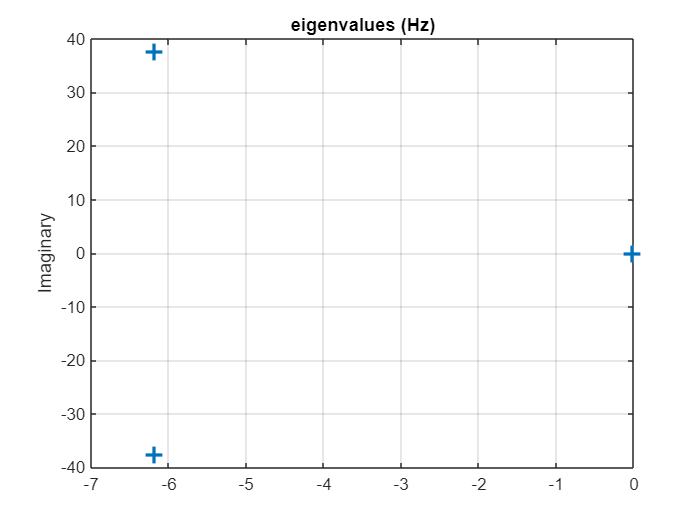

M = 3; % order of the system. 
[U,S,V] = svd(D); 

U_prime= U(:,1:M);
U1 = U_prime(1:L+1, :);
U2 = U_prime(2:end, :); 

Lambda_MP = inv(U2'*U1)*(U2'*U2);
z_MP=eig(Lambda_MP);
eig_s_MP = log(z_MP)/dT;

figure(889);
plot((real(eig_s_MP)/2/pi), ((imag(eig_s_MP))/2/pi),'+','Linewidth',2, 'Markersize',10);
ylabel('Imaginary')
title('identified eigenvalues (Hz)'); grid on;

### Signal reconstruction


for i1=1:N_MP+1;
    for j1=1:M;
        Z_MP(i1,j1)=z_MP(j1)^(i1-1);
    end 
end
for i=1:size(ya,2) 
residue1_MP(:,i) = pinv(Z_MP)*ya(:,i);
y_hat_MP(:,i)=Z_MP*residue1_MP(:,i);
end
figure;
plot(t, y_hat_MP.'); hold on;

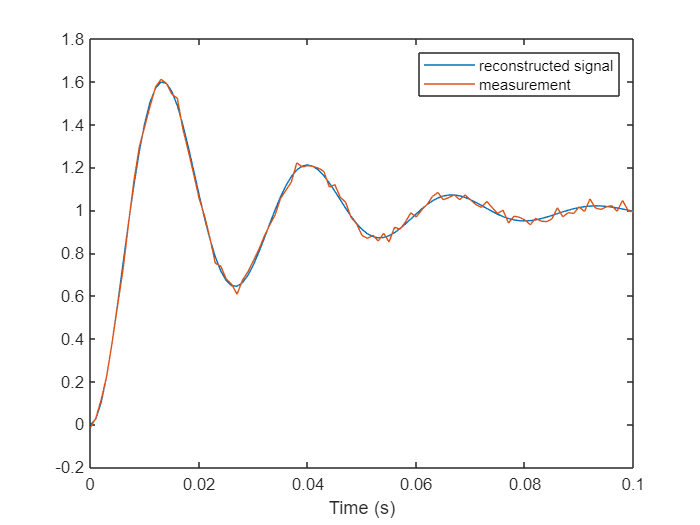

plot(t, vc1);
legend('reconstructed signal','measurement');
xlabel('Time (s)')